# ModCon - Aula 02

#### Exemplo 01 - Plot

Vs = 10

Vs = 10

R = 100

R = 100

C =0.01

C = 0.0100

t = 0:0.001:10

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


b = 0


ic = Vs/R*(exp(-t/(R*C)))

ic =     0.1000    0.0999    0.0998    0.0997    0.0996    0.0995    0.0994    0.0993    0.0992    0.0991    0.0990    0.0989    0.0988    0.0987    0.0986    0.0985    0.0984    0.0983    0.0982    0.0981    0.0980    0.0979    0.0978    0.0977    0.0976    0.0975    0.0974    0.0973    0.0972    0.0971    0.0970    0.0969    0.0969    0.0968    0.0967    0.0966    0.0965    0.0964    0.0963    0.0962    0.0961    0.0960    0.0959    0.0958    0.0957    0.0956    0.0955    0.0954    0.0953    0.0952


vc = Vs*(1-exp(-t/(R*C)))

vc =          0    0.0100    0.0200    0.0300    0.0399    0.0499    0.0598    0.0698    0.0797    0.0896    0.0995    0.1094    0.1193    0.1292    0.1390    0.1489    0.1587    0.1686    0.1784    0.1882    0.1980    0.2078    0.2176    0.2274    0.2371    0.2469    0.2566    0.2664    0.2761    0.2858    0.2955    0.3052    0.3149    0.3246    0.3343    0.3439    0.3536    0.3632    0.3729    0.3825    0.3921    0.4017    0.4113    0.4209    0.4305    0.4400    0.4496    0.4591    0.4687    0.4782


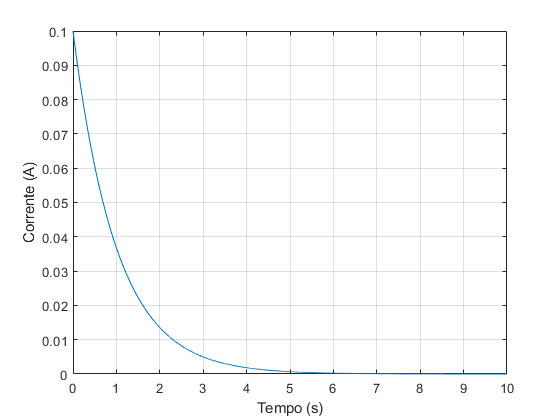


plot(t,ic);
grid on;
xlabel('Tempo (s)')
ylabel('Corrente (A)')

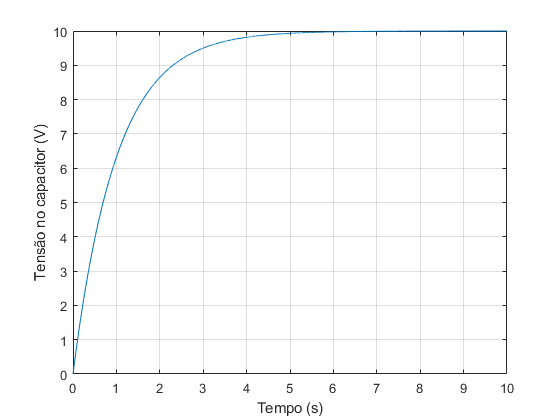


plot(t,vc);
grid on;
xlabel('Tempo (s)')
ylabel('Tensão no capacitor (V)')

#### Exemplo 01 - Symbolic Math

clear Vs R C t vc % remover essas variáveis
syms Vs t R C
syms ic(t) vc(t)


Corrente

odei = R*diff(ic(t),t) + ic(t)/C == 0

$$odei = R\,\frac{\partial }{\partial t}\mathrm{ic}\left(t\right)+\frac{\mathrm{ic}\left(t\right)}{C}=0$$

condi = ic(0) == Vs/R

$$condi = \mathrm{ic}\left(0\right)=\frac{\mathrm{Vs}}{R}$$


i_sol = dsolve(odei,condi)

$$i\_sol = \frac{\mathrm{Vs}\,{\mathrm{e}}^{-\frac{t}{C\,R}}}{R}$$


i_sol_n = subs(i_sol,{R C Vs},{100 0.01 10})

$$i\_sol\_n = \frac{{\mathrm{e}}^{-t}}{10}$$

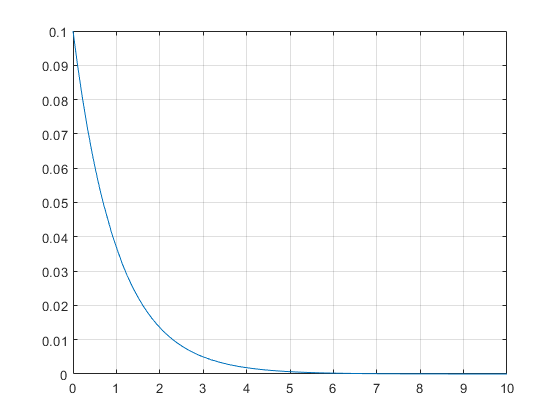


fplot(i_sol_n,[0 10])
grid on

Tensão

odev = R*C*diff(vc(t),t) + vc(t) -Vs == 0

$$odev = C\,R\,\frac{\partial }{\partial t}\mathrm{vc}\left(t\right)-\mathrm{Vs}+\mathrm{vc}\left(t\right)=0$$

condv = vc(0) == 0

$$condv = \mathrm{vc}\left(0\right)=0$$


v_sol = dsolve(odev,condv)

$$v\_sol = \mathrm{Vs}-\mathrm{Vs}\,{\mathrm{e}}^{-\frac{t}{C\,R}}$$


v_sol_n = subs(v_sol,{R C Vs},{100 0.01 10})

$$v\_sol\_n = 10-10\,{\mathrm{e}}^{-t}$$

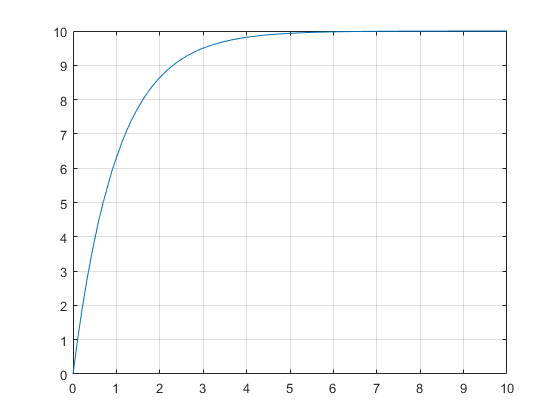


fplot(v_sol_n,[0 10])
grid on